clc;
clear;

%%%% getting path
% addpath(genpath('control/xytheta'));

% load ('femm_output.mat')
% load ('test_revised05.09.mat')

load('femm_out_sensor48_x[0,1]_y[2,10].mat')

Ts = 1e-5

Ts = 1.0000e-05

fs_theta = 180000;
f_theta = 18000/fs_theta

f_theta = 0.1000

numframe_theta = 1;

% % -1.5:0.5:1.5
% x_var = -1.5:0.5:1.5;
% x_var = [x_var x_var x_var x_var x_var x_var x_var x_var x_var];
% x_sampletime = 0.1;
% y_var = -1.5:0.5:1.5;
% y_sampletime = 0.7;

% -1.5:0.25:1.5
x_var = x_position;
y_var = y_position;
theta_var = 0:0.01:180;

x_sampletime = 0.1;
y_sampletime = x_sampletime * length(x_var)

y_sampletime = 0.2000

theta_var = repmat(theta_var,1,length(y_var)*length(x_var));
stop_time= f_theta*length(y_var)*length(x_var);
x_var = repmat(x_var,1,length(y_var));

% stop_time= 0.1;



x_total_out =[];
y_total_out =[];


% simulink
open('xytheta_microcontroller.slx');
out = sim('xytheta_microcontroller');

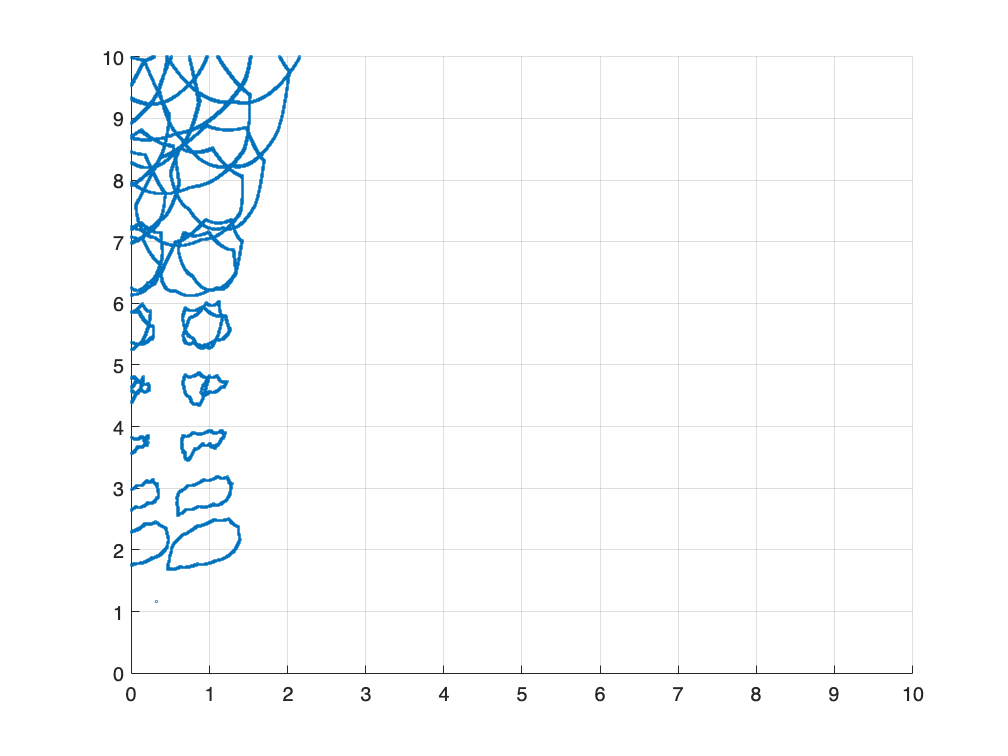


x_out = out.x_out';
y_out = out.y_out';
theta_out = out.theta_out';

scatter(x_out,y_out,1)
ylim([0 10])
xlim([0 10])
grid on

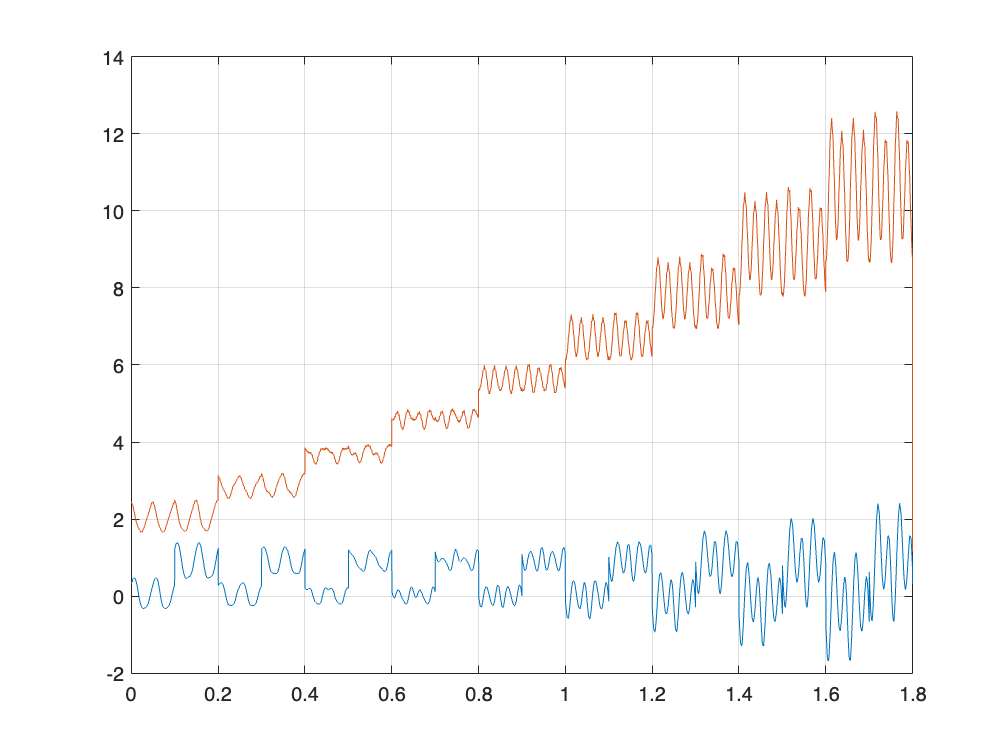

tt = linspace(0,stop_time,length(x_out));
plot(tt, x_out, tt, y_out)
% ylim([-2 2])
xlim([0 stop_time])
grid on

mean(y_out(1,1:length(y_out)/length(y_var)))

ans = 2.0271

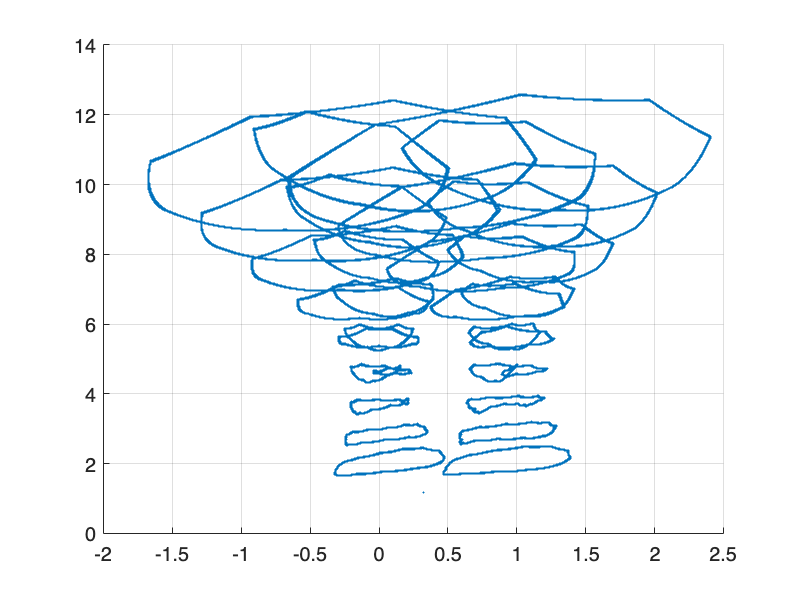

x_total_out = [x_total_out x_out];
y_total_out = [y_total_out y_out];
scatter(x_total_out, y_total_out,0.5)
% ylim([-2 2])
% xlim([-2 2])
grid on

save('xytheta/LUT_output/xy_out_sensor_r43_degree5_kg3000.mat',"x_total_out","y_total_out","theta_out");
% save('xy_out_sensor_r48_degree5_kg4250_mesh_1_0.2_0.2_0.5.mat',"x_total_out","y_total_out","theta_out")